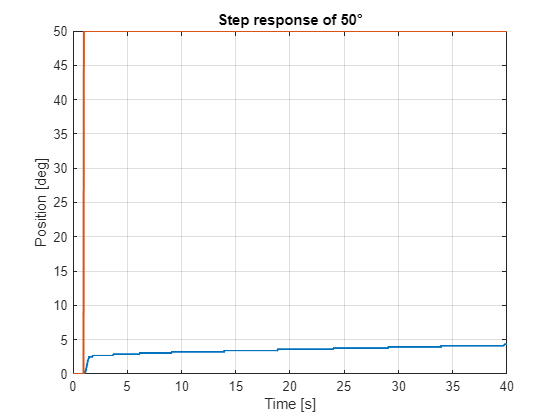

step_gain = 50;

simOut_2_3_2_50 = sim('Point_2_3\2_3_2\State_space_validation_2_3_2.slx');

% Create plots
% Define the step amplitude vector

figure; 
plot(simOut_2_3_2_50.theta_h_encoder.time,squeeze(simOut_2_3_2_50.theta_h_encoder.signals.values), 'LineWidth', 1.5);
grid on;
hold on;
plot(simOut_2_3_2_50.theta_h_ref.time,squeeze(simOut_2_3_2_50.theta_h_ref.signals.values), 'LineWidth', 1.5);
title(sprintf('Step response of %d°', step_gain));
xlabel('Time [s]');
ylabel('Position [deg]');